## Crank-Nicolson method

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.5*rand(Nx,Ny));
Z0 = predator * (1 + 0.5*rand(Nx,Ny));
Dp = 1e-5; Dz = 1e-5;
n = 1000; t_end = 24;

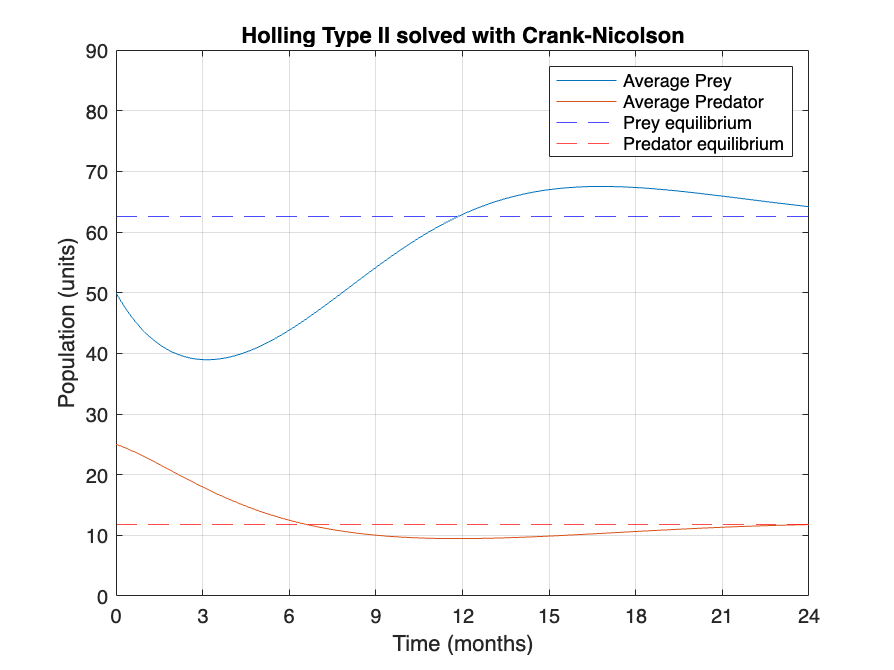

[t,P,Z] = CrankNicolsonDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II solved with Crank-Nicolson")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Holling Type II spacetime representation (horizontal slices)')

Holling Type II spacetime representation (horizontal slices)


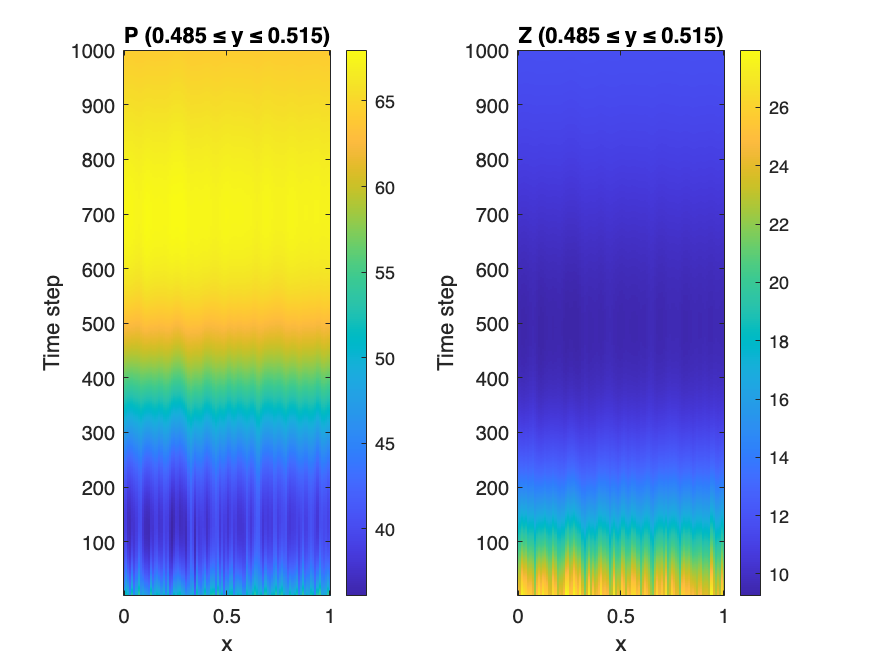

SpacetimeBand(P, Z, 0.5, 0.05)

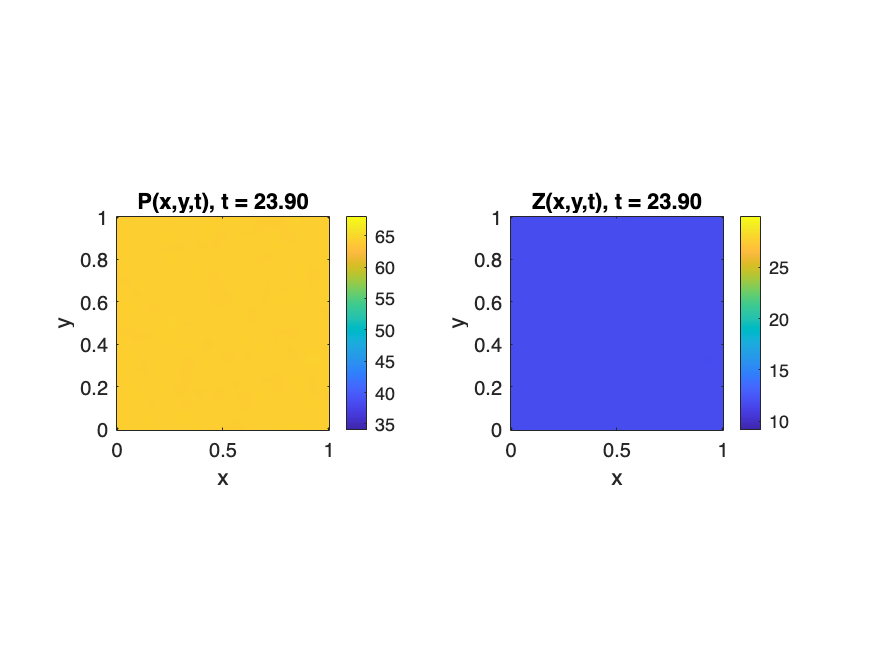


DiffusionPlot(t,P,Z)

This method shows similar results as the Euler implementation for slow diffusion problems. However, due to not having a stability condition on diffusion, it allows for stability on diffusion dominated problems

## Euler numerical collapse

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.5*rand(Nx,Ny));
Z0 = predator * (1 + 0.5*rand(Nx,Ny));
Dp = 2e-4; Dz = 1e-4;
n = 100; t_end = 24;

[~, n_min] = CFL(Dp,Dz,Nx,Ny,t_end)

n_min = 189

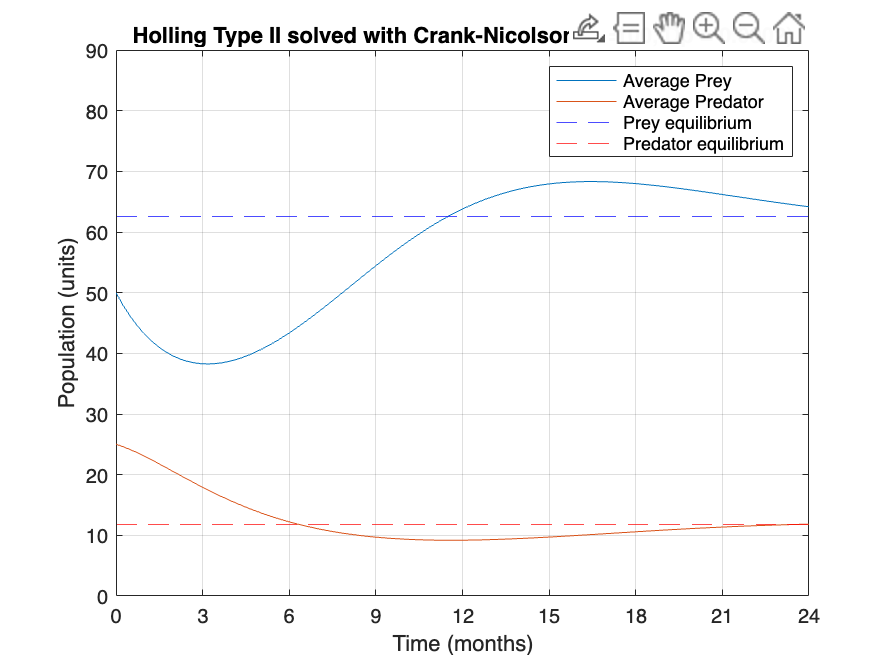

[t,P,Z] = CrankNicolsonDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II solved with Crank-Nicolson (n=" + n +", Dp = "+ Dp +")")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

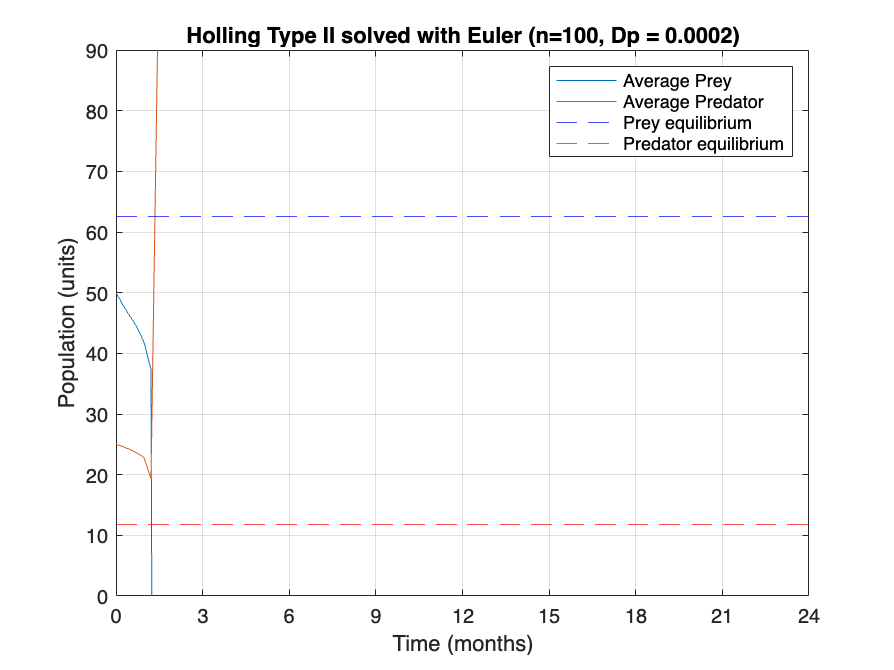


[t,P,Z] = EulerDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II solved with Euler (n=" + n +", Dp = "+ Dp +")")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

When diffusion coefficients are increased, and the number of timesteps are reduced, it can be seen how CN remains stable, while explicit Euler quickly collapses.